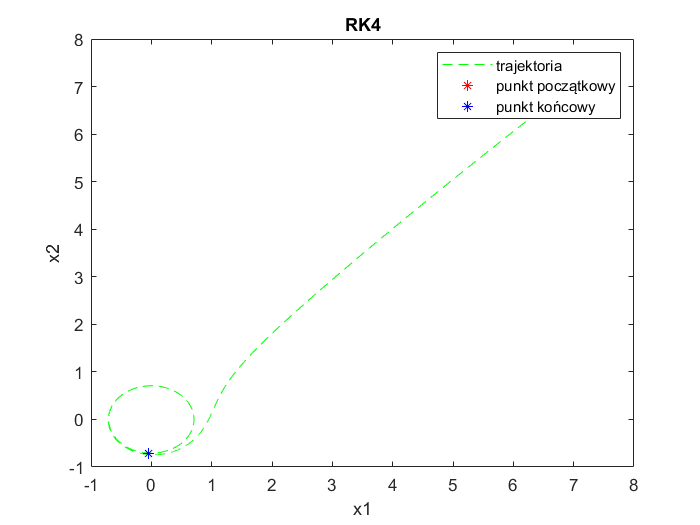

initial_cond = [8,8 ; 0,0.5 ; 10,0 ; 0.001,0.01; 0,-0.1];
example = 1;
krok_rk4 = 0.001;
krok_pc = 0.001;
data_rk4 = RK4(krok_rk4, initial_cond(example,:));
%plot(t(1:end-1), data)
plot(data_rk4(:,1), data_rk4(:,2), '--g', data_rk4(1,1), data_rk4(1,2), '*r', data_rk4(end,1), data_rk4(end,2), '*b')
legend('trajektoria', 'punkt początkowy', 'punkt końcowy');
title('RK4');
xlabel('x1');
ylabel('x2');

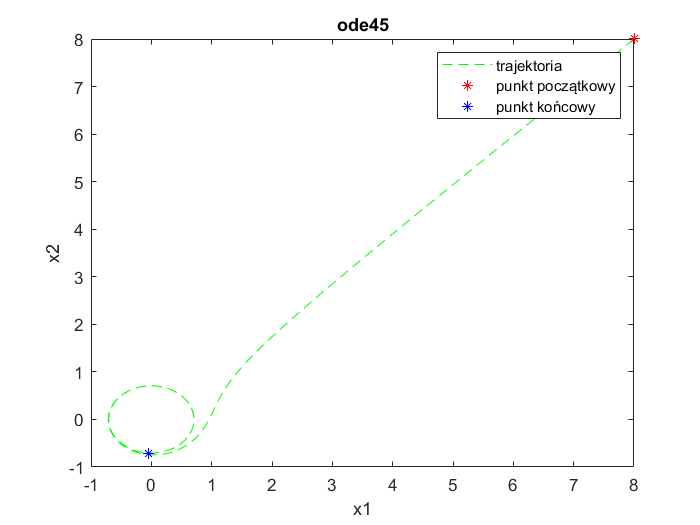


fun = @(t,x) [x(2) + x(1)*(0.5 - x(1).^2 - x(2).^2); -x(1) + x(2)*(0.5 - x(1).^2 - x(2).^2)];
tspan = [0, 15];
[t, data_ode] = ode45(fun, tspan, initial_cond(example,:));
plot(data_ode(:,1), data_ode(:,2), '--g', data_ode(1,1), data_ode(1,2), '*r', data_ode(end,1), data_ode(end,2), '*b')
legend('trajektoria', 'punkt początkowy', 'punkt końcowy');
title('ode45');
xlabel('x1');
ylabel('x2');

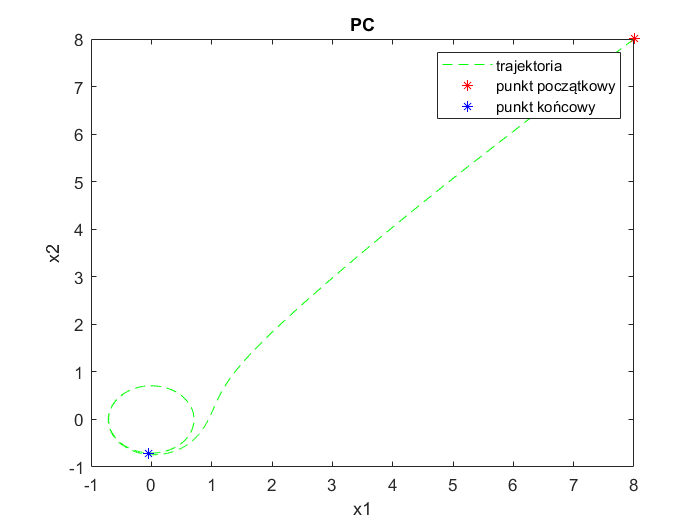



data_pc = predictor_corrector(krok_pc, initial_cond(example,:));
plot(data_pc(:,1), data_pc(:,2), '--g', data_pc(1,1), data_pc(1,2), '*r', data_pc(end,1), data_pc(end,2), '*b')
legend('trajektoria', 'punkt początkowy', 'punkt końcowy');
title('PC');
xlabel('x1');
ylabel('x2');